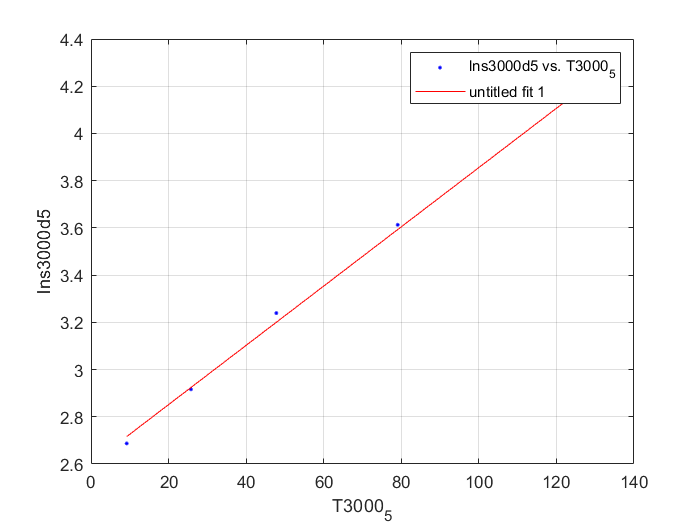

[xData, yData] = prepareCurveData( T3000_5, lns3000d5 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns3000d5 vs. T3000_5', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel T3000_5
ylabel lns3000d5
grid on


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01255  (0.01146, 0.01364)
  %     p2 =       2.601  (2.521, 2.68)

%Goodness of fit:
 % SSE: 0.003322
  %R-square: 0.9978
 % Adjusted R-square: 0.997
  %RMSE: 0.03328